# Next Paper, Journal?

### TO DO

- degradation parameter std should start off large and then update based on the true system filters

- parallelize digitaltwin execution, gather total flight times, create distribution. this is RUL for next true system flight

### Load paths and variables

addpath(genpath(pwd));
load_fresh_workspace;
load_trajectory;
%init_simulation_params;

### Simulate

Mode Selection 

- true system - nominal

- true system - degraded

- digital twin - nominal

- digital twin - degraded

sys = "TrueSystem";
%sys = "DigitalTwin";

mode = "Nominal";
%mode = "Degraded";

% degraded_level needs fixed to reflect the non-accelerated degradation
% profiles, before 11 was really degraded, now it is hardly
degraded_level = 11;

Degraded or Nominal

if mode == "Degraded"
    battery.R0=rdeg(degraded_level);
    battery.Q=qdeg(degraded_level);
    Motor2.Req=mdeg(degraded_level);
    Motor4.Req=mdeg(degraded_level);
else
    battery.R0=rdeg(1);
    battery.Q=qdeg(1);
    Motor2.Req=mdeg(1);
    Motor4.Req=mdeg(1);
end

if sys == 'TrueSystem'
    octomodel.sampletime = .025;
    disp('true system simulation');
    load_system('truesystem');
    tic
    sim('truesystem.slx');
    toc
else
    batterytwin = battery;
    Motortwin2 = Motor2;
    Motortwin4 = Motor4;
    octomodel.sampletime = .05;
    load_system('digitaltwin1c');

true system simulation


Elapsed time is 229.979292 seconds.


    tic

rul = 19.4500

    sim('digitaltwin1c.slx');
    toc
end
rul = flight_time.Data(end)

## Plot Path

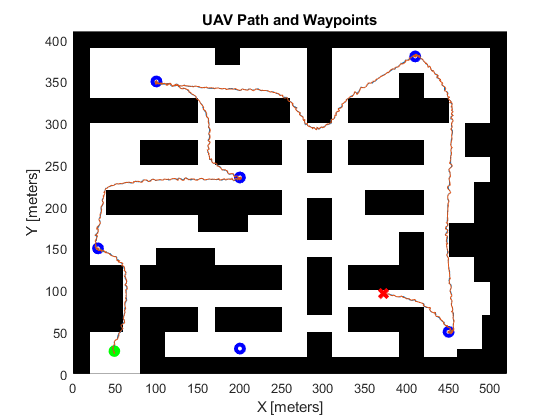

f1 = figure(1); clf;
hold on;
show(map);
plot(pos_observed.Data(1,1), pos_observed.Data(1,2), 'go', 'markerfacecolor', 'g', 'markersize', 8);
for i = 1:length(waypoints)
   plot(waypoints(i,1), waypoints(i,2), 'bo', 'LineWidth', 3); 
end
plot(pos_actual.Data(:,1), pos_actual.Data(:,2));
plot(pos_observed.Data(:,1), pos_observed.Data(:,2));
if ~any(stop_code.Data(:,3))

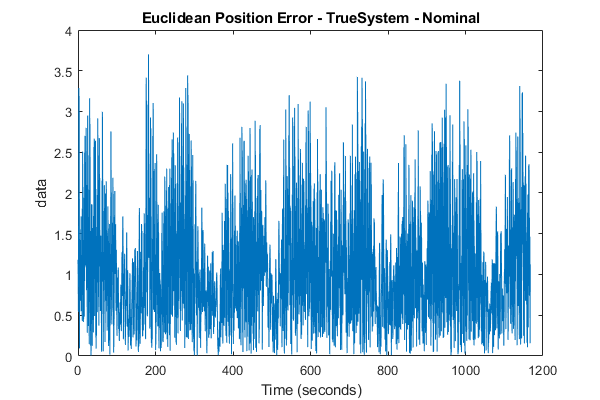

    plot(pos_observed.Data(end, 1), pos_observed.Data(end, 2), 'rx', 'markersize', 9, 'LineWidth', 3);
end
hold off;
title("UAV Path and Waypoints");

## Euclidean Position Error

f2 = figure(2); clf;
plot(euclidean_pos_err);
ttl = sprintf("%s - %s - %s", 'Euclidean Position Error', sys, mode);
title(ttl);

## Voltage and SOC Plot

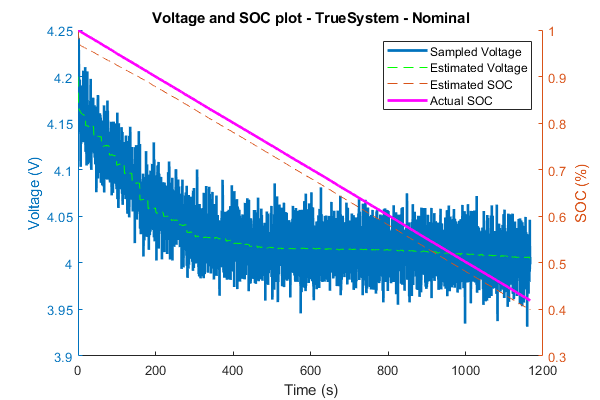

f2 = figure(2); clf;
f2.Position = [0 0 600 400];
yyaxis left;
hold on;
plot(battery_observed.Time(:), battery_observed.Data(:,1), 'linewidth', 2, "DisplayName", "Sampled Voltage");
plot(battery_actual.Time(:), battery_actual.Data(:,1), 'g', "DisplayName", "Estimated Voltage");
hold off;
ylabel("Voltage (V)");
yyaxis right;
hold on;
plot(battery_observed.Time(:), battery_observed.Data(:,2), '--', "DisplayName", "Estimated SOC");
plot(battery_actual.Time(:), battery_actual.Data(:,2),'m-', 'linewidth', 2, "DisplayName", "Actual SOC");
hold off;
ttl = sprintf("%s - %s - %s", 'Voltage and SOC plot', sys, mode);

title(ttl);
xlabel("Time (s)");
ylabel("SOC (%)");
legend();

## Current Plot

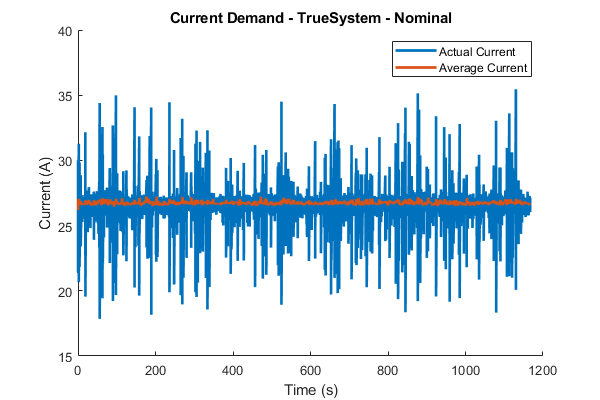

f2 = figure(2); clf;
f2.Position = [0 0 600 400];
hold on;
plot(current_actual.Time(:,1), current_actual.Data(:,1), 'linewidth', 2, "DisplayName", "Actual Current");
plot(downsample(current_actual.Time(:,1), 5),smoothdata(downsample(current_actual.Data(:,1), 5), 'rlowess', 20), 'linewidth', 2, "DisplayName", "Average Current");
ttl = sprintf("%s - %s - %s", 'Current Demand', sys, mode);
title(ttl);

xlabel("Time (s)");

r0_var = 0.0022

Q_var = 0.9487

ylabel("Current (A)");
ylim([15 40]);
legend();


# *********************************************************************************************************************

# Simulation Loop 

# *********************************************************************************************************************

- load main workspace 

addpath(genpath(pwd));
load_fresh_workspace;
load_trajectory;


- main loop

% counter for each true system simulation
true_ctr = 1;

% counter for combining parallel simulation results
idx_ctr = 1;
% loop 


Elapsed time is 236.458192 seconds.


octomodel.sampletime = true_sample_rate;

r_var = 0.0021

tic

q_var = 0.9487

sim('truesystem.slx');

m_var = 0.0020

toc
r_var = battery_observed.Data(end, 5)
q_var = battery_observed.Data(end, 7)
m_var = motors.Data(2, 4)
battery.R0 = normrnd(rdeg(true_ctr), r_var);
battery.Q = normrnd(qdeg(true_ctr), q_var);
Motor2.Req = normrnd(mdeg(true_ctr), m_var);

- define placeholder variables

twin_flight_times(true_ctr,:) = zeros(1,48);
twin_voltages(true_ctr,:) = zeros(1,48);
twin_socs(true_ctr,:) = zeros(1,48);
twin_r0s(true_ctr,:) = zeros(1,48);
twin_qs(true_ctr,:) = zeros(1,48);
twin_mot_res(true_ctr,:) = zeros(1,48);
twin_pos_errs(true_ctr,:) = zeros(1,48);

- now simulate digital twin 48 times (12 cores x 4 iterations)

octomodel.sampletime = twin_sample_rate;
numRuns = 12;
for twin_ctr=1:4
    tic
    for n = 1:numRuns
        in(n) = Simulink.SimulationInput("digitaltwin1c");
    end
    tic
    out = parsim(in, 'ShowSimulationManager',"off", 'ShowProgress',"off", "UseFastRestart", "on", "SetupFcn", @()load_workspace(true_ctr, r_var, q_var, m_var, twin_sample_rate));
    toc
    for run_ctr = 1:numRuns
        times(run_ctr) = out(run_ctr).flight_time.Data(end);
        vs(run_ctr) = out(run_ctr).battery_actual.Data(end, 1);
        socs(run_ctr) = out(run_ctr).battery_actual.Data(end, 2);
        r0s(run_ctr) = out(run_ctr).battery_actual.Data(end, 3);
        qs(run_ctr) = out(run_ctr).battery_actual.Data(end, 6);
        ms(run_ctr) = out(run_ctr).motors.Data(end, 1);
        errs(run_ctr) = mean(out(run_ctr).euclidean_pos_err);
        sprintf("err: %f", errs(run_ctr))
    end
    sprintf("true_ctr: %d\tidx_ctr: %d\tr*t: %d \n", true_ctr, idx_ctr, run_ctr*twin_ctr)
    twin_flight_times(true_ctr,idx_ctr:twin_ctr*run_ctr) = times; 
    twin_voltages(true_ctr,idx_ctr:twin_ctr*run_ctr) = vs;
    twin_socs(true_ctr,idx_ctr:twin_ctr*run_ctr) = socs;
    twin_r0s(true_ctr,idx_ctr:twin_ctr*run_ctr) = r0s;
    twin_qs(true_ctr,idx_ctr:twin_ctr*run_ctr) = qs;
    twin_mot_res(true_ctr,idx_ctr:twin_ctr*run_ctr) = ms;
    twin_pos_errs(true_ctr,idx_ctr:twin_ctr*run_ctr) = errs;

Starting parallel pool (parpool) using the 'local' profile ...
Preserving jobs with IDs: 1 because they contain crash dump files.
You can use 'delete(myCluster.Jobs)' to remove all jobs created with profile local. To create 'myCluster' use 'myCluster = parcluster('local')'.
Connected to the parallel pool (number of workers: 12).
Analyzing and transferring files to the workers ...done.


Elapsed time is 279.852699 seconds.


ans = "err: 1.787012"

ans = "err: 1.771220"

ans = "err: 1.772158"

ans = "err: 1.772461"

ans = "err: 1.774503"

ans = "err: 1.785848"

ans = "err: 1.792359"

ans = "err: 1.772868"

ans = "err: 1.774427"

ans = "err: 1.766457"

ans = "err: 1.782866"

ans = "err: 1.793568"

ans =     "true_ctr: 1	idx_ctr: 1	r*t: 12 
     "


Elapsed time is 238.657358 seconds.


ans = "err: 1.766130"

ans = "err: 1.769684"

ans = "err: 1.758266"

ans = "err: 1.789920"

ans = "err: 1.769659"

ans = "err: 1.808766"

ans = "err: 1.773075"

ans = "err: 1.777532"

ans = "err: 1.776621"

ans = "err: 1.785848"

ans = "err: 1.798543"

ans = "err: 1.786109"

ans =     "true_ctr: 1	idx_ctr: 13	r*t: 24 
     "


Elapsed time is 221.354638 seconds.


ans = "err: 1.794756"

ans = "err: 1.772743"

ans = "err: 1.784399"

ans = "err: 1.794927"

ans = "err: 1.785801"

ans = "err: 1.765787"

ans = "err: 1.785848"

ans = "err: 1.816432"

ans = "err: 1.780339"

ans = "err: 1.761614"

ans = "err: 1.801385"

ans = "err: 1.792132"

ans =     "true_ctr: 1	idx_ctr: 25	r*t: 36 
     "


Elapsed time is 223.588205 seconds.


ans = "err: 1.757396"

ans = "err: 1.790455"

ans = "err: 1.801477"

ans = "err: 1.784847"

ans = "err: 1.779996"

ans = "err: 1.807721"

ans = "err: 1.791226"

ans = "err: 1.785848"

ans = "err: 1.762741"

ans = "err: 1.754965"

ans = "err: 1.780790"

ans = "err: 1.762875"

ans =     "true_ctr: 1	idx_ctr: 37	r*t: 48 
     "


  Columns 1 through 15

   19.6933   19.1100   19.1100   19.8667   19.8667   19.3267   18.4867   19.8667   19.8767   19.8767   19.0133   19.8667   18.7100   19.1100   19.3267

  Columns 16 through 30

   19.3267   19.1100   18.0067   18.4867   19.3267   19.8767   19.3267   17.4267   19.3267   18.8867   19.8767   19.1100   18.8867   18.3400   19.8667

  Columns 31 through 45

   19.3267   17.4267   19.0133   19.8767   18.4867   17.7067   19.8667   19.3267   19.3267   19.8667   19.3267   17.5433   18.0500   19.3267   19.8767

  Columns 46 through 48

   19.6933   19.3267   19.8767



    idx_ctr = twin_ctr * numRuns + 1;

  Columns 1 through 15

    3.9666    3.9544    3.9730    3.9713    3.9847    4.0309    3.9656    4.0125    3.9357    4.0184    4.0117    4.0126    4.0023    3.9578    4.0046

  Columns 16 through 30

    3.9296    3.9296    3.9706    3.9982    3.9250    4.0046    4.0309    3.9804    3.9489    3.9689    3.9937    4.0051    3.9986    4.0265    3.9769

  Columns 31 through 45

    4.0309    3.9925    3.9866    4.0087    3.9511    3.9526    4.0244    4.0242    4.0204    3.9593    3.9474    3.9858    3.9832    4.0309    3.9025

  Columns 46 through 48

    3.9908    3.9400    3.9295



  Columns 1 through 15

    0.4096    0.4099    0.4109    0.4078    0.4077    0.4120    0.4097    0.4078    0.4082    0.4080    0.4111    0.4076    0.4095    0.4108    0.4092

  Columns 16 through 30

    0.4150    0.4106    0.4063    0.4102    0.4118    0.4080    0.4120    0.4068    0.4127    0.4088    0.4079    0.4103    0.4080    0.4098    0.4077

  Columns 31 through 45

    0.4120    0.4083    0.4071    0.4079    0.4100    0.4090    0.4076    0.4155    0.4161    0.4077    0.4177    0.4108    0.4142    0.4120    0.4079

  Columns 46 through 48

    0.4092    0.4173    0.4080



end

  Columns 1 through 15

    0.0025    0.0029    0.0022    0.0022    0.0017    0.0001    0.0025    0.0008    0.0035    0.0005    0.0008    0.0008    0.0011    0.0027    0.0010

  Columns 16 through 30

    0.0038    0.0038    0.0023    0.0013    0.0039    0.0010    0.0001    0.0020    0.0031    0.0023    0.0015    0.0011    0.0013    0.0003    0.0020

  Columns 31 through 45

    0.0001    0.0015    0.0016    0.0009    0.0030    0.0029    0.0003    0.0003    0.0005    0.0026    0.0031    0.0018    0.0018    0.0001    0.0047

  Columns 46 through 48

    0.0015    0.0033    0.0037



disp(twin_flight_times(true_ctr,:))

  Columns 1 through 15

   15.3970   14.9667   14.9842   15.5000   15.5000   15.1845   14.4762   15.5000   15.5000   15.5000   14.9152   15.5000   14.6328   14.9793   15.1197

  Columns 16 through 30

   15.2606   14.9739   14.0148   14.4847   15.1840   15.5000   15.1845   13.5799   15.1992   14.7661   15.5000   14.9688   14.7423   14.3596   15.5000

  Columns 31 through 45

   15.1845   13.6055   14.8078   15.5000   14.4771   13.8429   15.4884   15.2705   15.2900   15.5000   15.3324   13.7654   14.2490   15.1845   15.5000

  Columns 46 through 48

   15.3940   15.3267   15.5000



disp(twin_voltages(true_ctr,:))

  Columns 1 through 15

    0.2374    0.2348    0.2349    0.2375    0.2358    0.2377    0.2372    0.2377    0.2396    0.2399    0.2347    0.2371    0.2378    0.2381    0.2395

  Columns 16 through 30

    0.2376    0.2354    0.2345    0.2374    0.2361    0.2379    0.2377    0.2377    0.2358    0.2371    0.2352    0.2362    0.2379    0.2365    0.2349

  Columns 31 through 45

    0.2377    0.2375    0.2387    0.2382    0.2356    0.2361    0.2386    0.2379    0.2372    0.2366    0.2327    0.2381    0.2353    0.2377    0.2341

  Columns 46 through 48

    0.2396    0.2339    0.2346



disp(twin_socs(true_ctr,:))

  Columns 1 through 15

    1.7870    1.7712    1.7722    1.7725    1.7745    1.7858    1.7924    1.7729    1.7744    1.7665    1.7829    1.7936    1.7661    1.7697    1.7583

  Columns 16 through 30

    1.7899    1.7697    1.8088    1.7731    1.7775    1.7766    1.7858    1.7985    1.7861    1.7948    1.7727    1.7844    1.7949    1.7858    1.7658

  Columns 31 through 45

    1.7858    1.8164    1.7803    1.7616    1.8014    1.7921    1.7574    1.7905    1.8015    1.7848    1.7800    1.8077    1.7912    1.7858    1.7627

  Columns 46 through 48

    1.7550    1.7808    1.7629



disp(twin_r0s(true_ctr,:))
disp(twin_qs(true_ctr,:))
disp(twin_mot_res(true_ctr,:))
disp(twin_pos_errs(true_ctr,:))
i = i + 1;

## Parallel Testing

- get average runtime of of iteration without parallelism

load_system('digitaltwin1c');
runs = 5;
tic
for i = 1:runs
    load_fresh_workspace;

rul = 19.6933

rul = 20.2633

rul = 19.9867

rul = 19.6600

rul = 20.1867

    octomodel.sampletime = .05;

t2 = 786.9818

    sim("digitaltwin1c.slx");

ans = 157.3964

    rul = flight_time.Data(end)
end
t2 = toc
t2/runs

Parallel testing with parameters in setup function

arg1 = .03;
%evalin('base', 'partest.m')
for i = 1:5

Analyzing and transferring files to the workers ...done.


    in(i) = Simulink.SimulationInput('simpartest');
end

out = parsim(in, 'ShowSimulationManager',"off", 'ShowProgress',"off", "UseFastRestart", "on", "SetupFcn", @()partest(867));

res = 872.5466

res = 870.1727

res = 842.8379

res = 872.0269

res = 868.6979

for i = 1:5
    res = out(i).res.Data(1,1)
   
end

numRuns = 6;
tic
for i = 1:numRuns
    in(i) = Simulink.SimulationInput("digitaltwin1c");
end
tic
out = parsim(in, 'ShowSimulationManager',"off", 'ShowProgress',"off", "UseFastRestart", "on", "SetupFcn", @()load_workspace(i, r_var, q_var, m_var));
toc


for i = 1:numRuns
    times(i) = out(i).flight_time.Data(end);
    vs(i) = out(i).battery_actual.Data(end, 1);
    socs(i) = out(i).battery_actual.Data(end, 2);
    r0s(i) = out(i).battery_actual.Data(end, 3);
    qs(i) = out(i).battery_actual.Data(end, 6);
    ms(i) = out(i).motors.Data(end, 1);
end
disp(times)
disp(r0s)
disp(socs)
disp(qs)
avg_time = sum(times)/length(times)




